## Problem **CT considering magnetizing characteristic**

Let us consider a CT with a turns ratio of 600:5, and the magnetizing characteristic corresponding to this ratio is shown below.

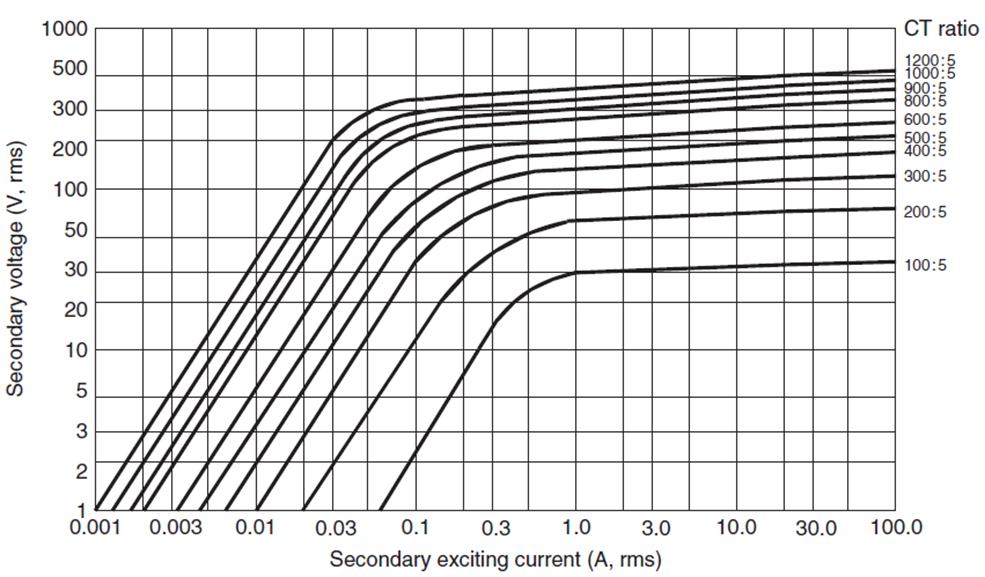

Magnetizing characteristic or Secondary excitation curves for various turn ratios of a specific CT [1]

It is required to calculate the current in its secondary winding for a primary current of *I**1*= 5,000 A, if the total burden impedance is *Z**b*= (9.0 + *j*2.0)W and the secondary leakage impedance is negligible.

The impedance angle of the *magnetizing **branch *is 60◦.

Since the magnetizing branch is *nonlinear*.

Calculate the per unit CT error (e).

Calculate the ratio correction factor. 

        Created by: Professor Francisco Gonzalez-Longatt, January 2020, [fglongatt@fglongatt.org](mail: fglongatt@fglongatt.org) 

        Github: [https://github.com/fglongatt/ElectricalPowerAnalysis](https://github.com/fglongatt/ElectricalPowerAnalysis) 

Input data

a = 600/5

a = 120

Zb = (9+2*i); 
I1 = 5000

I1 = 5000

The secondary current (*I1p*) is calculated as:

I1p = I1/a

I1p = 41.6667

fprintf('|I1| = %5.5f A', I1p)

|I1| = 41.66667 A

The corresponding Thevenin equivalent (Vth) consists of a voltage source:

Vth = I1p * Zb

Vth = 3.7500e+02 + 8.3333e+01i

fprintf('Vth = (%5.5f + %5.5f) V', real(Vth), imag(Vth))

Vth = (375.00000 + 83.33333) V

fprintf('Vth = (%5.5f ∠ %5.5f°) V', abs(Vth), angle(Vth)*180/pi)

Vth = (384.14769 ∠ 12.52881°) V

Now, the resolution of this problem is based on a graphical method.

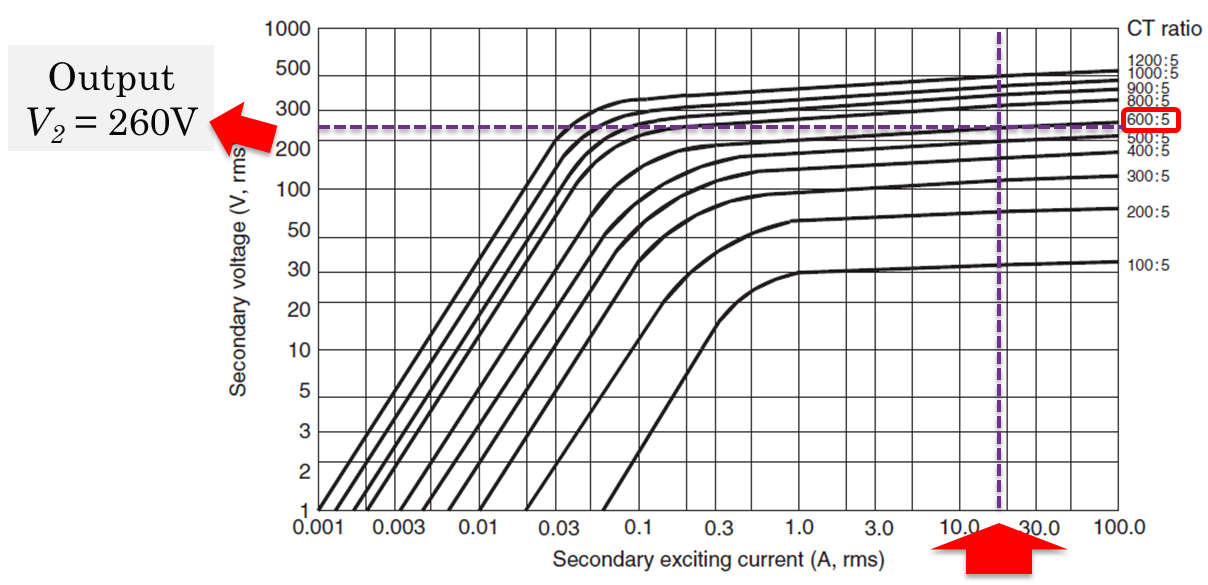

From the graphic method

Im = 17

Im = 17

V2 = 260

V2 = 260

The magnetizing impedance (Zm):

Zm = V2/Im

Zm = 15.2941

Zm = Zm* (cos(60*pi/180) + i * sin(60*pi/180));

Zm = 7.6471 + 13.2451i

fprintf(' Zm = (%5.5f + %5.5f) A', real(Zm), imag(Zm))
fprintf('Zm = (%5.5f ∠ %5.5f°) A', abs(Zm), angle(Zm)*180/pi)

Calculating the magnettizing current (Im):

Im = Vth/(Zm + Zb)

Im = 14.7449 - 8.4972i

fprintf('Im = (%5.5f + %5.5f) A', real(Im), imag(Im))

Im = (14.74489 + -8.49723) A

fprintf('Im = (%5.5f ∠ %5.5f°) A', abs(Im), angle(Im)*180/pi)

Im = (17.01806 ∠ -29.95412°) A

Calculating the secundary current (I2):

I2 = I1p - Im;
fprintf('I2 = (%5.5f + %5.5f) A', real(I2), imag(I2))

I2 = (26.92178 + 8.49723) A

fprintf('I2 = (%5.5f ∠ %5.5f°) A', abs(I2), angle(I2)*180/pi)

I2 = (28.23093 ∠ 17.51708°) A

Calculating the per unit CT error (*ϵ*):

e = Im/I1p;
fprintf(' ϵ = (%5.5f ∠ %5.5f°) ', abs(e), angle(e)*180/pi)

 ϵ = (0.40843 ∠ -29.95412°) 

Calculating the ratio correction factor (*R*):

R = 1/(1-e);

R = 1.4075 - 0.4442i

fprintf(' R = (%5.5f ∠ %5.5f°) ', abs(R), angle(R)*180/pi)

 ϵ = (1.47592 ∠ -17.51708°) 